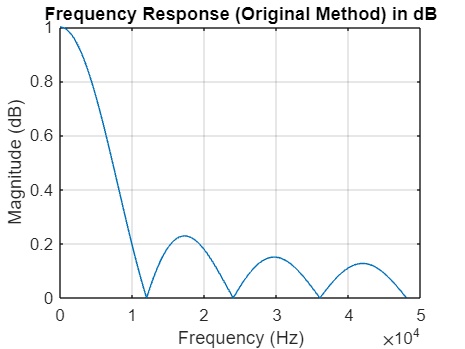

% Parameters
N = 8; % Window size
fs = 96000; % Sampling frequency
freq_points = 1000; % Number of frequency points

% Original method coefficients
b_1 = ones(1, N) / N; 
a_1 = 1; 

% Optimized method coefficients
b_2 = [1, zeros(1, N-1), -1] / N;
a_2 = [1, -1];

% Frequency response
[H_1, f] = freqz(b_1, a_1, freq_points, fs);
[H_2, f] = freqz(b_2, a_2, freq_points, fs);

figure;
plot(f, (abs(H_1)));
title('Frequency Response (Original Method) in dB');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

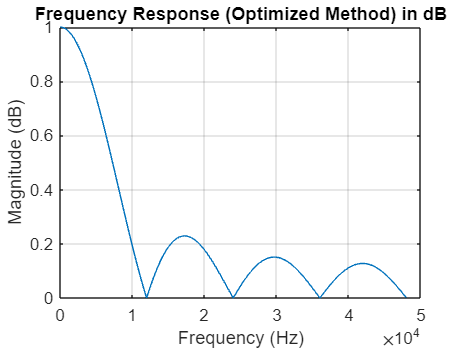


figure;
plot(f, (abs(H_2)));
title('Frequency Response (Optimized Method) in dB');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;